clc;
clearvars;
N = 10000; % Length of the x-axis, also known as the length of the random walks.
M = 10; % The amount of random walks.
x_t = ones(M,1)*100;
y_t = ones(M,1)*100;
indexx=randi(40,2000);
%indexx=ones(200);
step=10;
%%

index=randi(40,10000,1000);

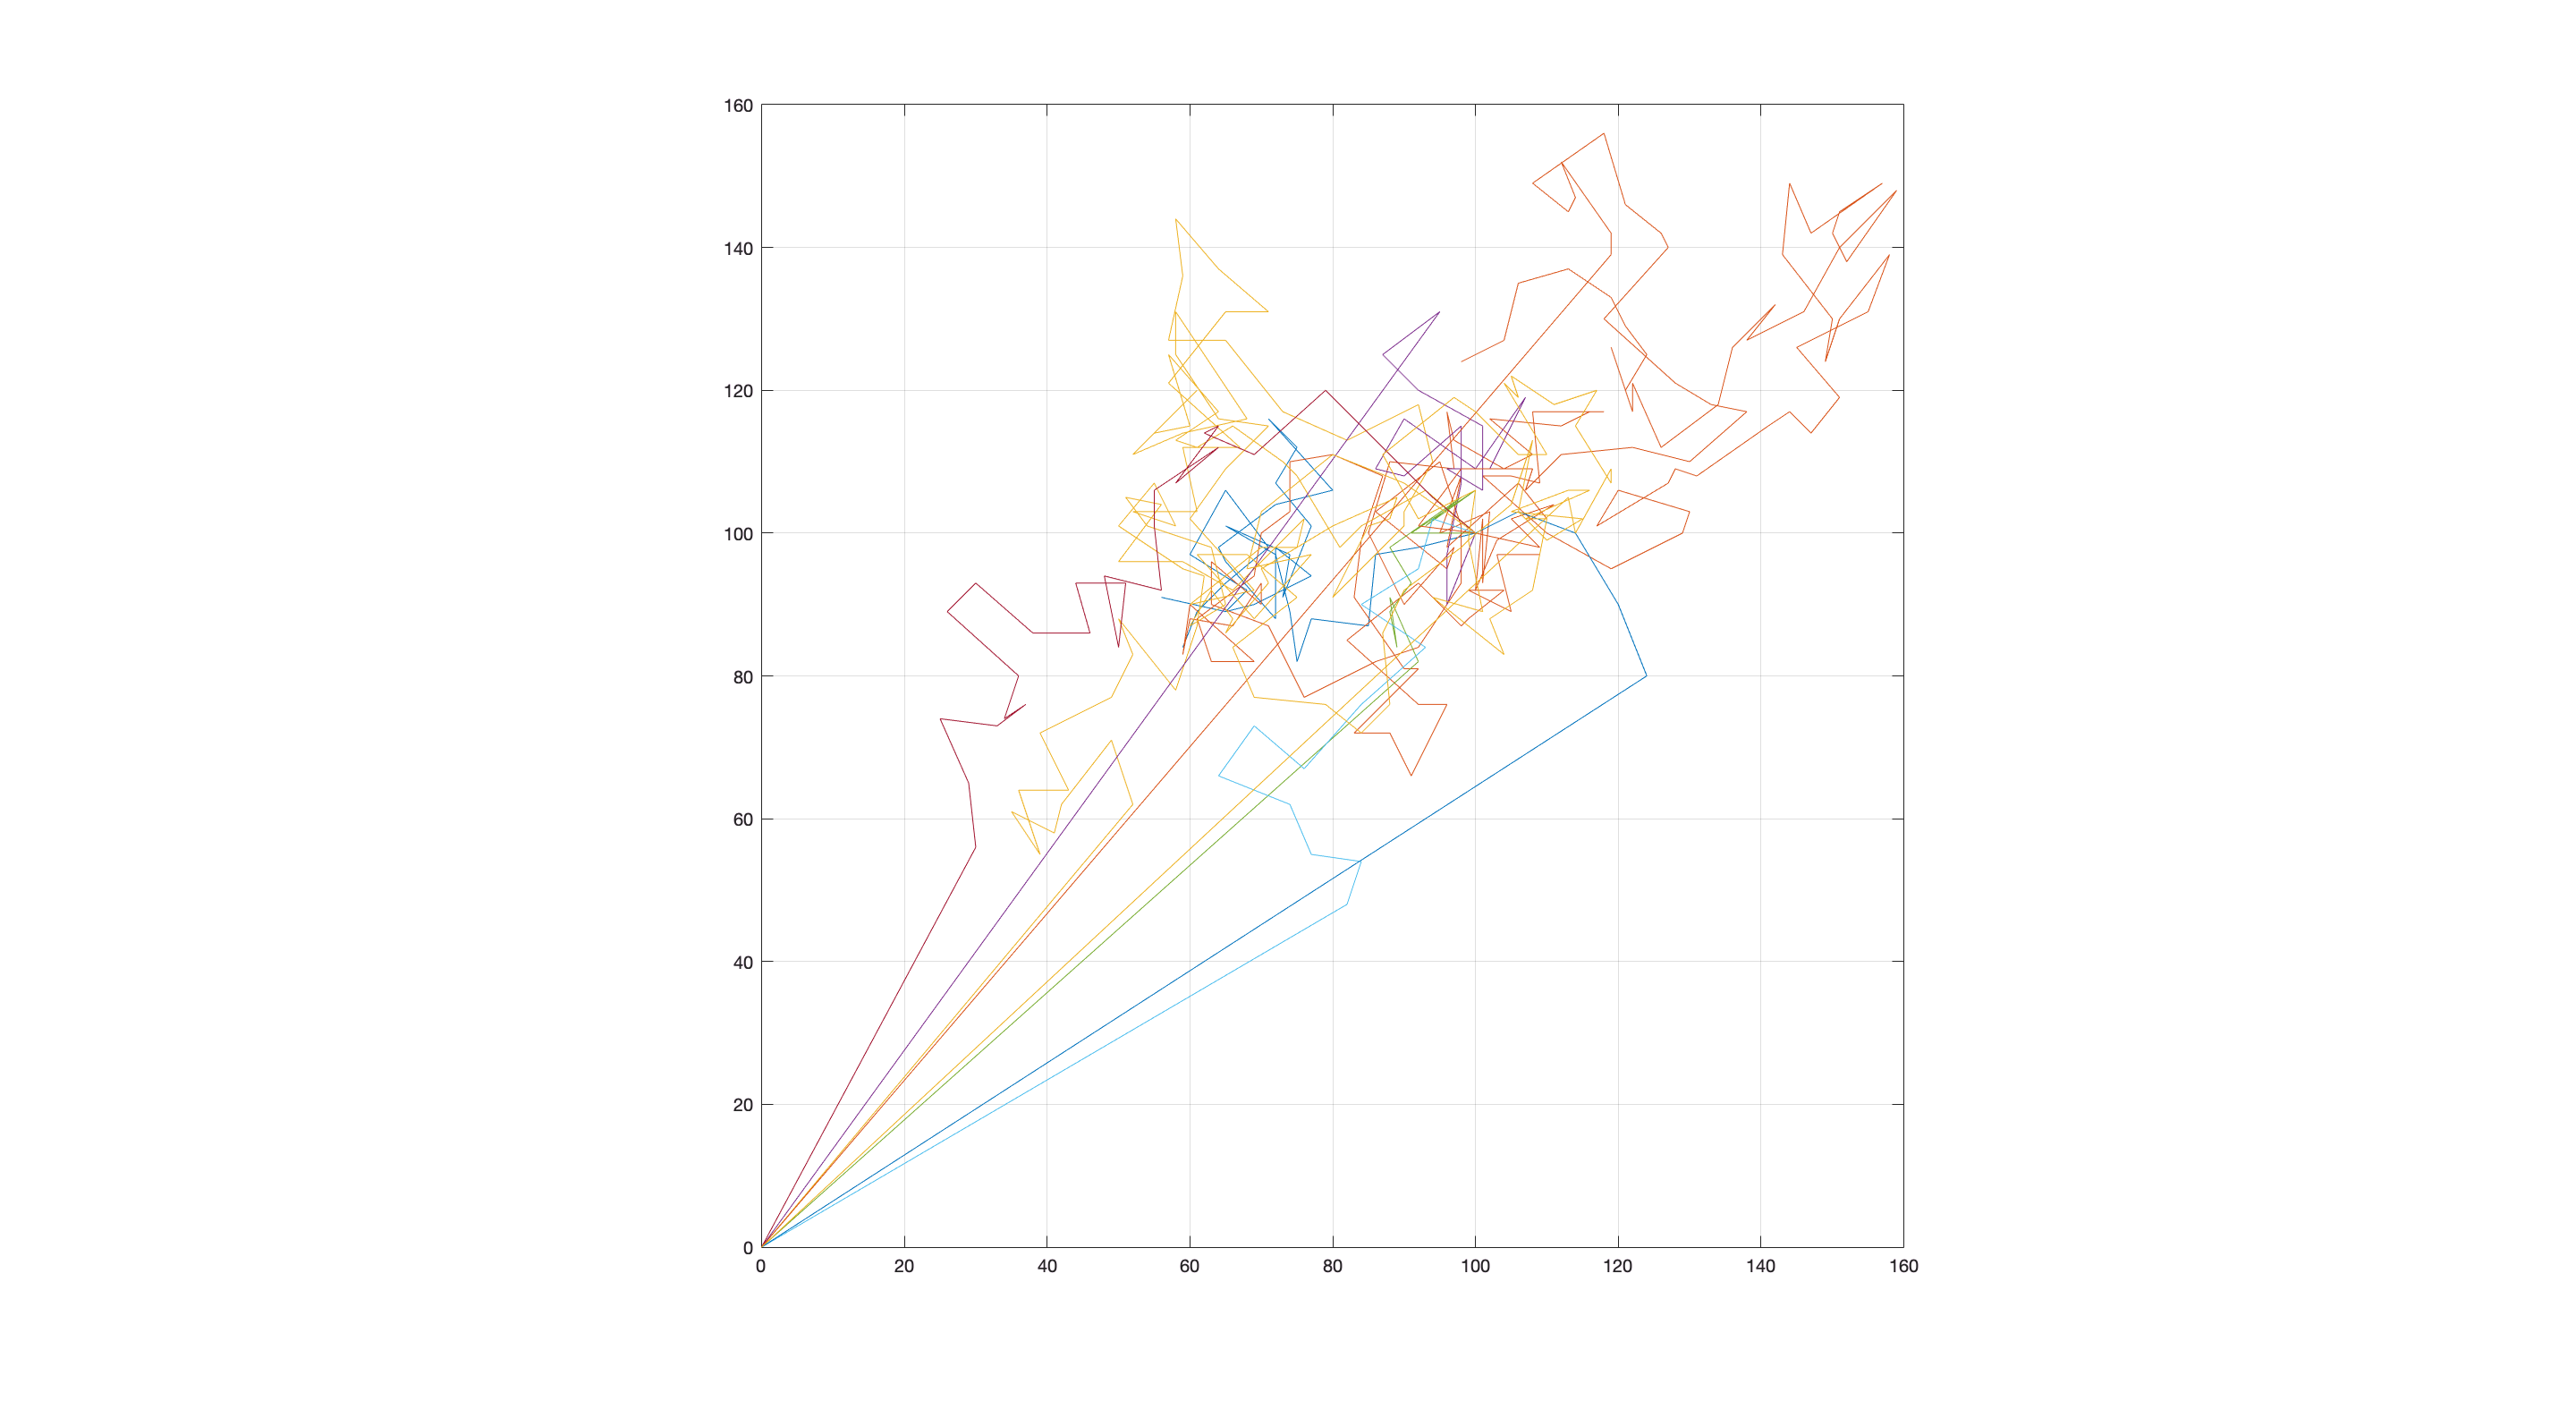

%for b=1:100:100000;
%index((1:100)+b,:)
for m=1:M
  for n = 1:N % Looping all values of N into x_t(n).
    if (indexx(x_t(m,n),y_t(m,n)))>1
    %A = sign(randn); % Generates either +1/-1 depending on the SIGN of RAND.
    A = randi([-step step],1);
    x_t(m,n+1) = x_t(m,n) + A;
    A = randi([-step step],1); % Generates either +1/-1 depending on the SIGN of RAND.
    y_t(m,n+1) = y_t(m,n) + A;
    dx(m,n+1)=cumsum(A);
    else
       break
    end
  end
  plot(x_t(m,:), y_t(m,:));
  hold on
end
%end
grid on;
% Enlarge figure to full screen.
set(gcf, 'Units', 'Normalized', 'Outerposition', [0, 0.05, 1, 0.95]);
axis square;

%%

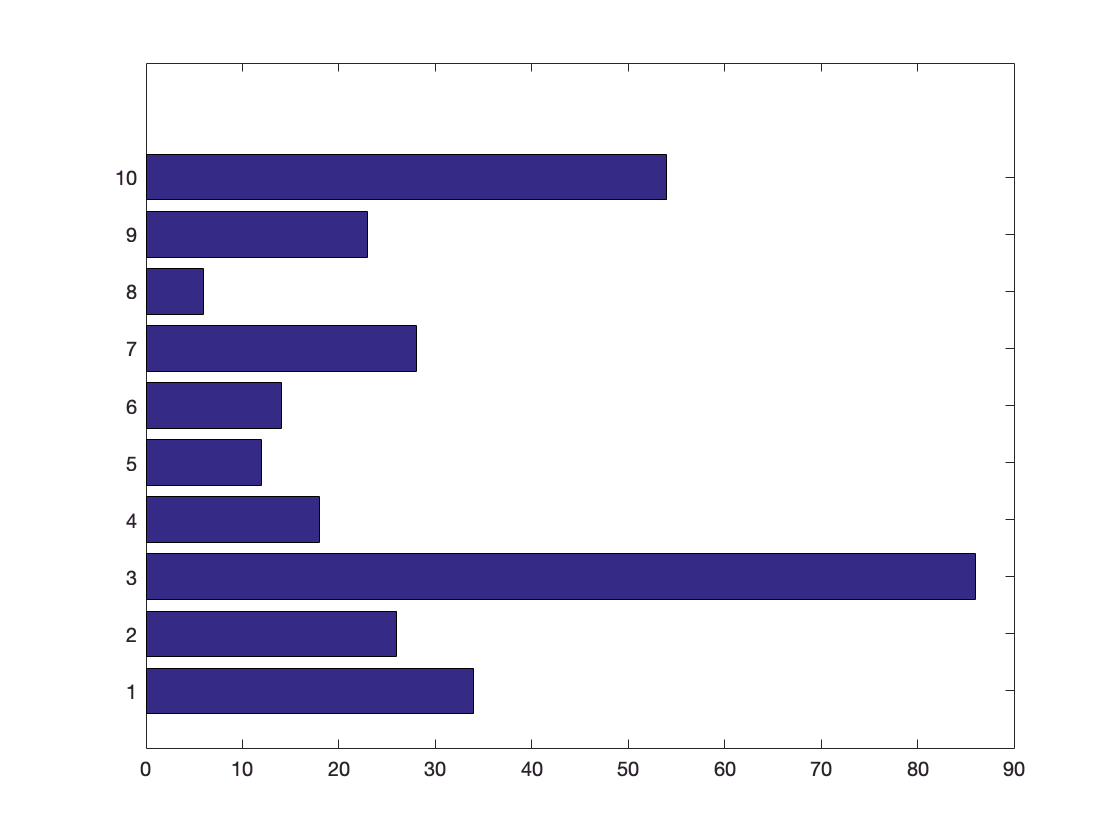


b = abs(x_t); % it is a trick which forces min to do not consider your negative numbers as minimum 
c = abs(y_t);
[~,ind] = min(b');
[~,ind] = min(c');
figure;barh(ind)

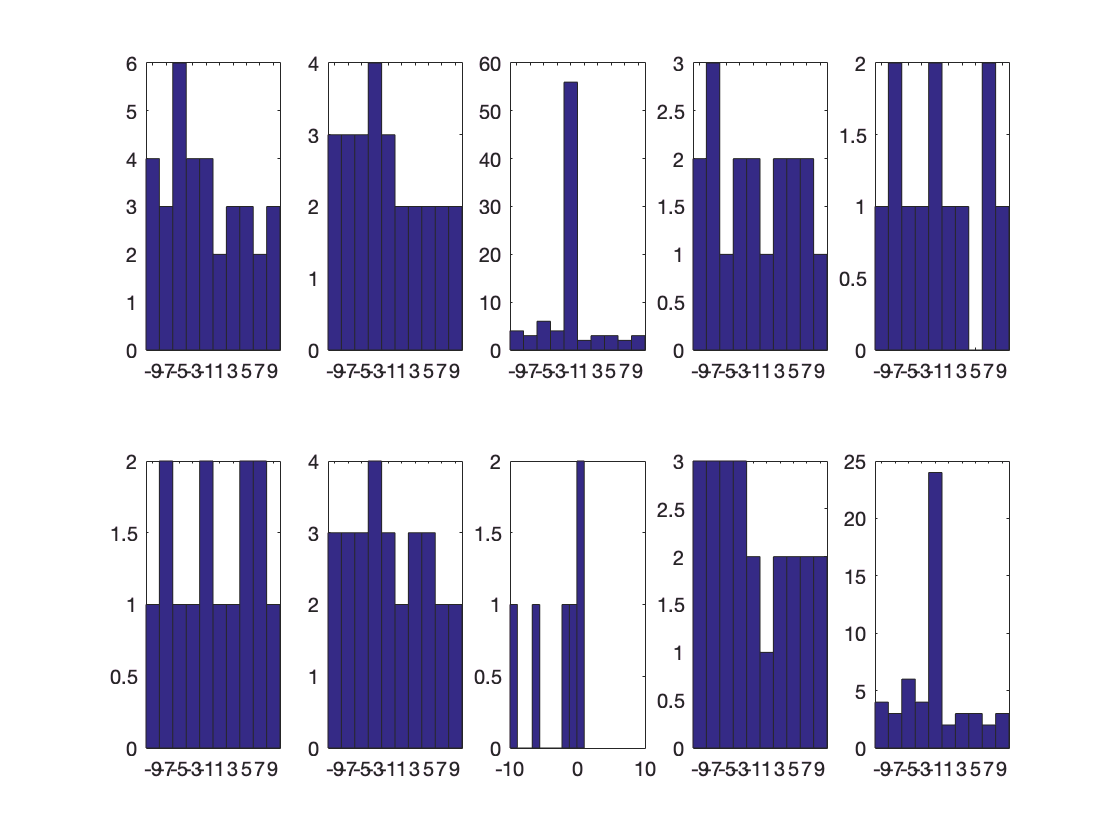

mean_ind=mean(ind);
median_ind=median(ind);
std_ind=std(ind);
figure;
for i=1:10
subplot(2,5,i);
hist(dx(1,1:ind(i)))
end